clear; clc;
addpath('/MATLAB Drive/Research/SLS_K_realization/structured_implementation/final code/other functions')
addpath('/MATLAB Drive/Research/SLS_K_realization/structured_implementation/final code/intermediate functions')
addpath('/MATLAB Drive/Research/SLS_K_realization/structured_implementation/final code')

The SLS state feedback controller synthesis problem is


$$\inf_{\Phi^x,\Phi^u}~~\|\mathcal{F}\big(P,\Phi^x,\Phi^u\big)\|\\
\mathrm{s.t.} ~~(\Phi^x,\Phi^u)\in(\mathcal{C}_x\times\mathcal{C}_u)\cap\frac{1}{s}\mathcal{RH}_\infty$$


where $\mathcal{C}_x$ and $\mathcal{C}_u$ are linear subspace constraints which enforce that the closed-loop responses $\Phi^x$ and $\Phi^u$ adhere to the block sparsity structure of some adjacency matrix $\mathcal{A}$.

It's shown in [Jensen and Bamieh 2020](https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=9147959) that when the closed-loop responses have block sparsity structure of $\mathcal{A}$, it is possible to construct a realization of the state feedback controller $u=Kx=\Phi^u(\Phi^x)^{-1}x$ for which each of $(A_K,B_K,C_K,D_K)$ have the block sparsity structure of $\mathcal{A}$.

Here we demonstrate how to use the code to go from structured transfer matrices $\Phi^x$ and $\Phi^u$ to a structured realization of $K$ ([which is stabilizable and detectable](https://www.overleaf.com/read/nvrytmyytmpp#957e75)).

Consider the case that network we hope to realize the controller over is


$$\mathcal{A} = \left[\begin{array}{ccc}1&0&1\\1&1&0\\0&0&1\end{array}\right]$$


Let $x=\left[\begin{array}{ccc}x_1^T&x_2^T&x_3^T\end{array}\right]^T$ with $x_1\in\mathbb{R}^1$, $x_2\in\mathbb{R}^2$, $x_3\in\mathbb{R}^3$ and $u=\left[\begin{array}{ccc}u_1^T&u_2^T&u_3^T\end{array}\right]^T$ with $u_1\in\mathbb{R}^2$, $u_2\in\mathbb{R}^1$, $u_3\in\mathbb{R}^2$. The partitions of $x$ and $u$ are then $\mathcal{P}_x=(1,2,3)$ and $\mathcal{P}_u=(2,1,2)$. $\Phi^x$ will have block rows and columns according to $\mathcal{P}_x$ while $\Phi^u$ will have rows partioned according to $\mathcal{P}_x$ and columns partitioned according to $\mathcal{P}_u$.

partition_x = [1,2,3]; partition_u = [2,1,2];

We will then have $\Phi^x$ and $\Phi^u$ of the form


$$\Phi^x = \left[\begin{array}{c|cc|ccc}
\phi_{11}^x&0&0&\phi_{14}^x&\phi_{15}^x&\phi_{16}^x\\
\hline
\phi_{21}^x&\phi_{22}^x&\phi_{23}^x&0&0&0\\
\phi_{31}^x&\phi_{32}^x&\phi_{33}^x&0&0&0\\
\hline
0&0&0&\phi_{44}^x&\phi_{45}^x&\phi_{46}^x\\
0&0&0&\phi_{54}^x&\phi_{55}^x&\phi_{56}^x\\
0&0&0&\phi_{64}^x&\phi_{55}^x&\phi_{56}^x\\
\end{array}\right]$$



$$\Phi^u=\left[\begin{array}{c|cc|ccc}
\phi_{11}^u&0&0&\phi_{14}^u&\phi_{15}^u&\phi_{16}^u\\
\phi_{21}^u&0&0&\phi_{24}^u&\phi_{25}^u&\phi_{26}^u\\
\hline
\phi_{31}^u&\phi_{32}^u&\phi_{33}^u&0&0&0\\
\hline
0&0&0&\phi_{44}^u&\phi_{45}^u&\phi_{46}^u\\
0&0&0&\phi_{54}^u&\phi_{55}^u&\phi_{56}^u\\
\end{array}\right]$$


Choose some arbitrary values for the nonzero transfer function elements.

phi1 = tf([1],[1,1]); phi2 = tf([1],[1,1,1]); phi3 = tf([1],[1,1,1,1]);
z = tf([0],[1]);
Phix = [phi1,z,z,phi1,phi2,phi3;
        phi1,phi2,phi3,z,z,z;
        phi1,phi2,phi3,z,z,z;
        z,z,z,phi1,phi2,phi3;
        z,z,z,phi1,phi2,phi3;
        z,z,z,phi1,phi2,phi3];
Phiu = [phi1,z,z,phi1,phi2,phi3;
        phi1,z,z,phi1,phi2,phi3;
        phi1,phi2,phi3,z,z,z;
        z,z,z,phi1,phi2,phi3;
        z,z,z,phi1,phi2,phi3];

To get a structured realization, we simply run the function $\texttt{structuredControllerRealization.m}$ with arguments $\Phi^x$, $\Phi^u$, $\mathcal{P}_x$, and $\mathcal{P}_u$. This function also returns the partition of the controller internal state $\xi_K$.

[K,partition_ksi_K] = structuredControllerRealization(Phix,Phiu,partition_x,partition_u);

We have also included the function $\texttt{ltiEquiv.m}$ to test that the realization of $K$is an equivalent system to the transfer matrix $\Phi^u(\Phi^x)^{-1}$:

ltiEquiv(K,Phiu/Phix);

systems are equivalent to within numerical precision


We have also included the function $\texttt{pltBlkSpstyRlztn.m}$ to verify the realization has the desired sparsity structure.

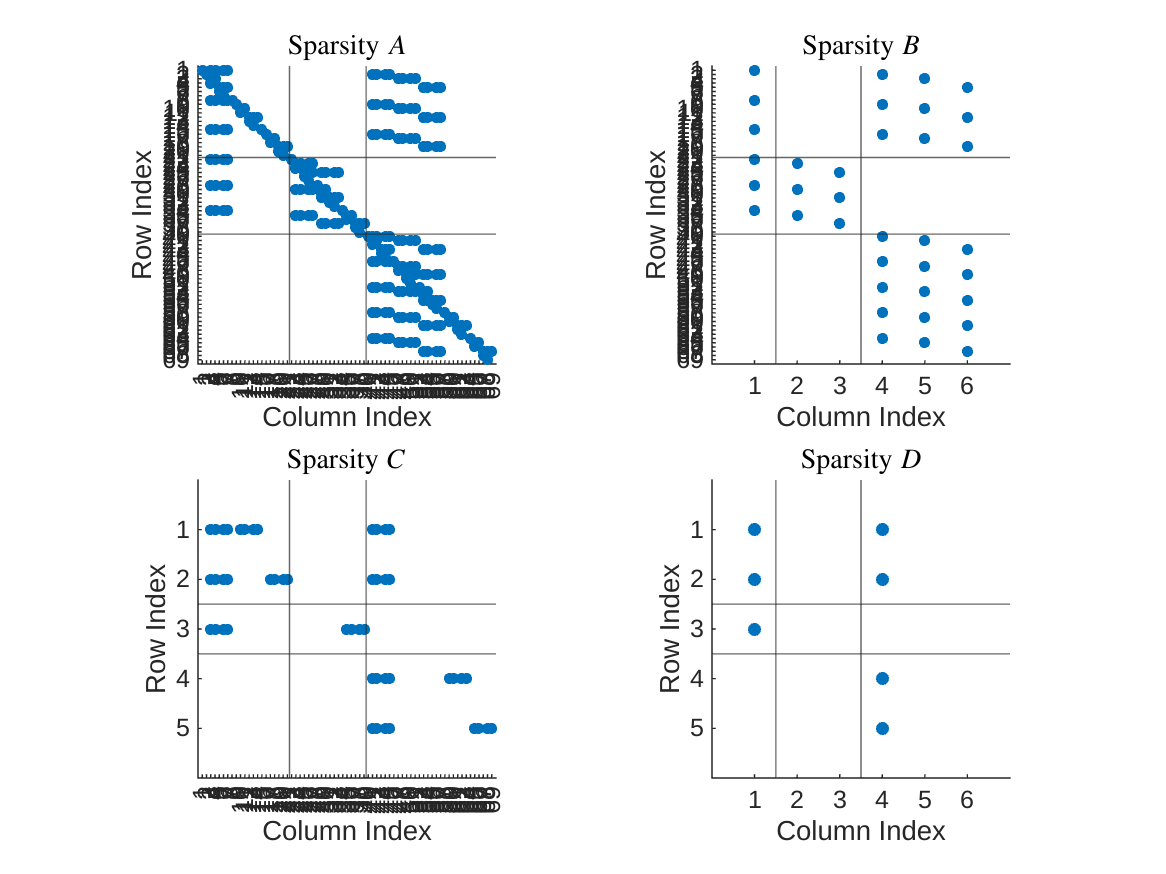

pltBlkSpstyRlztn(K,partition_ksi_K,partition_x,partition_u)